DBSCAN matlab function vs implementation (Same results)

Data = readmatrix('data_clustering.csv');

Data =     0.3209    0.8573
    0.1193    0.5777
    0.1068    0.7419
    0.4544    0.2875
    0.4487    0.2275
    0.1520    0.7467
    0.6149    0.4180
    0.4722    0.2461
    0.6699    0.4297
    0.4249    0.6499


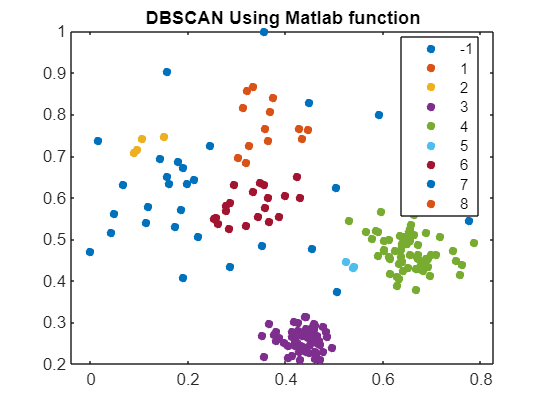

idx = dbscan(Data,0.05,3);
gscatter(Data(:,1),Data(:,2),idx)
hold on
title('DBSCAN Using Matlab function')
hold off

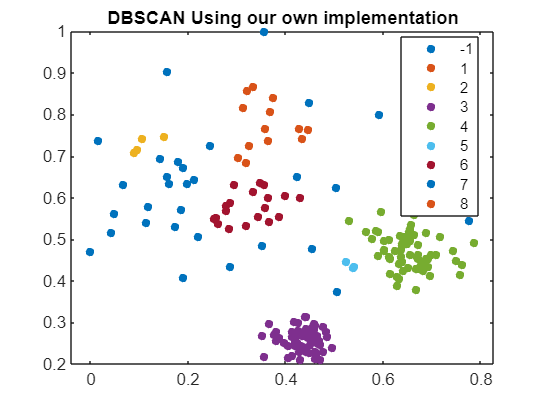


cluster = DBSCAN(Data,0.05,3);
gscatter(Data(:,1),Data(:,2),cluster)
hold on
title('DBSCAN Using our own implementation')
hold off

**Experimental results **

Qualitative results

– A figure displaying three plots obtained using k-nearest neighbour search and mark one possible elbow point on each plot to indicate the threshold value (t) for parameter eps. Here we set k=3,4,5. You can use the built-in function for k-nearest neighbour search/graph 3.

clusterDBSCAN.estimateEpsilon(Data,3,5)

'clusterDBSCAN.estimateEpsilon'
requires Radar Toolbox.

hold on
title("k-nearest neighbour search")
hold off

epsilon = clusterDBSCAN.estimateEpsilon(Data,3,5)

– A figure displaying the resulting clusters and outliers (minPts=k, eps=t).

clusterer = clusterDBSCAN('MinNumPoints',3,'Epsilon',epsilon, ...
    'EnableDisambiguation',false);
idx = clusterer(Data);
plot(clusterer,Data,idx)
hold on
title("Resulting clusters and outliers for minPts=3,eps=0.0495")
xlabel("Feature 1")
ylabel("Feature 2")
hold off

clusterer = clusterDBSCAN('MinNumPoints',4,'Epsilon',epsilon, ...
    'EnableDisambiguation',false);
idx = clusterer(Data);
plot(clusterer,Data,idx)
hold on
title("Resulting clusters and outliers for minPts=4,eps=0.0495")
xlabel("Feature 1")
ylabel("Feature 2")
hold off

clusterer = clusterDBSCAN('MinNumPoints',5,'Epsilon',epsilon, ...
    'EnableDisambiguation',false);
idx = clusterer(Data);
plot(clusterer,Data,idx)
hold on
title("Resulting clusters and outliers for minPts=5,eps=0.0495")
xlabel("Feature 1")
ylabel("Feature 2")
hold off

Quantitative results 

– A table listing the computed silhouette score for different parameter setting of eps=t and minPts=3,4,5 (in total, 3 silhouette scores). You can use the same built-in function used in the previous assignment.

clusterIdx = kmeans(Data,3);
s=silhouette(Data,clusterIdx,'Euclidean'); %default is sqEuclidean but we use euclidean distance to compute silhouette scores
K3=mean(s);

clusterIdx = kmeans(Data,4);
s=silhouette(Data,clusterIdx,'Euclidean'); %default is sqEuclidean but we use euclidean distance to compute silhouette scores
K4=mean(s);

clusterIdx = kmeans(Data,5);
s=silhouette(Data,clusterIdx,'Euclidean'); %default is sqEuclidean but we use euclidean distance to compute silhouette scores
K5=mean(s);

SilhouetteScore = table(K3,K4,K5,'VariableNames',{'K=3','K=4','K=5'},'RowNames',{'Silhouette score'})

**BONUS**

load('thyroid.mat')
clusterDBSCAN.estimateEpsilon(X,3,5)
hold on
title("k-nearest neighbour search")
hold off
epsilon = clusterDBSCAN.estimateEpsilon(X,3,5)

%For k=3
idxK3 = dbscan(X,epsilon,3);
TP=0;TN=0;FN=0;FP=0;
for i=1:size(X,1)
    if y(i)==1
        if idxK3(i)==-1
            TP=TP+1;
        else
            FN=FN+1;
        end
    else
        if idxK3(i)~=-1
            TN=TN+1;
        else
            FP=FP+1;
            
        end
    end
end;
disp("Results for k=3")
Precision = TP/(TP+FP)
Recall = TP/(TP+FN)
Fscore = 2 *Precision*Recall/(Precision+Recall)

%For k=4
idxK4 = dbscan(X,epsilon,4);
TP=0;TN=0;FN=0;FP=0;
for i=1:size(X,1)
    if y(i)==1
        if idxK4(i)==-1
            TP=TP+1;
        else
            FN=FN+1;
        end
    else
        if idxK4(i)~=-1
            TN=TN+1;
        else
            FP=FP+1;
            
        end
    end
end;
disp("Results for k=4")
Precision = TP/(TP+FP)
Recall = TP/(TP+FN)
Fscore = 2 *Precision*Recall/(Precision+Recall)

%For k=5
idxK5 = dbscan(X,epsilon,5);
TP=0;TN=0;FN=0;FP=0;
for i=1:size(X,1)
    if y(i)==1
        if idxK5(i)==-1
            TP=TP+1;
        else
            FN=FN+1;
        end
    else
        if idxK5(i)~=-1
            TN=TN+1;
        else
            FP=FP+1;
            
        end
    end
end;
disp("Results for k=5")
Precision = TP/(TP+FP)
Recall = TP/(TP+FN)
Fscore = 2 *Precision*Recall/(Precision+Recall)